## Practica 1

### Ejercicio 1

#### Apartado a

Aplicar el ode45 un PVI

[t,y]=ode45(@(t,y)sin(y-t-1)^2,[0,1],2);

Solucion exacta: y(t) = 1 + t + arctan(tan(1)-t)

#### Apartado c

Representar solucion exacta y solucion aproximada

e=1+t+atan(tan(1)-t);
plot(t,e,'r*')
hold on
plot(t,y,'g-')

### Ejercicio 2

x^n + mu(x^2-1)x'+x=0

Para MATLAB (x(t), y(t)) <==> (y(1), y(2)

El sistema nos queda y'(1) = y(2), y'(2) = y(1) -(y(1)^2 -1)*y(1)

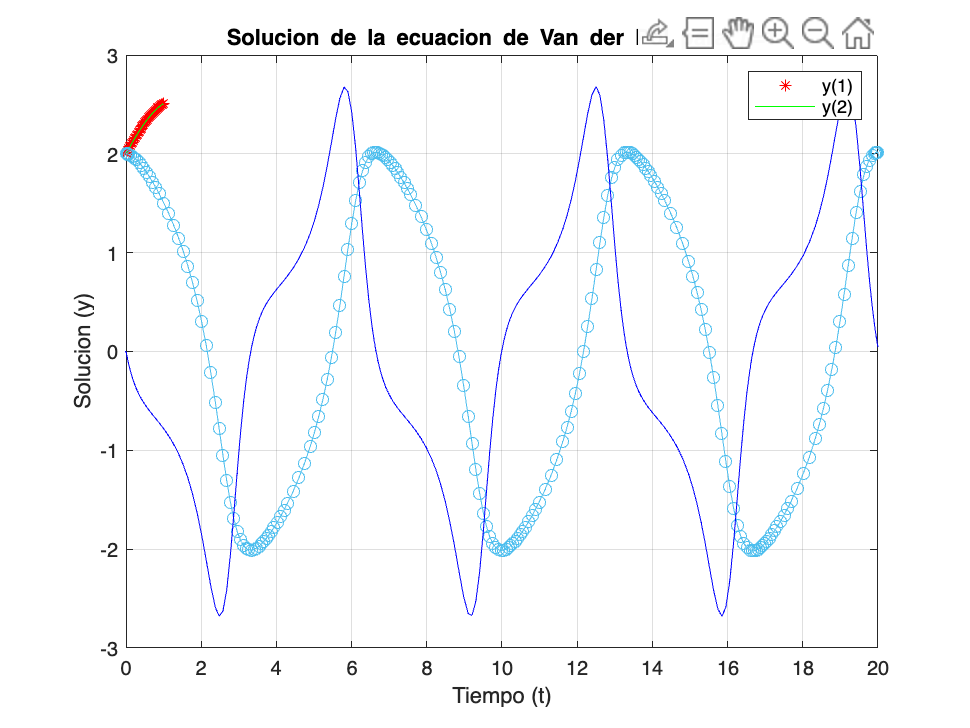

[t,y]=ode45(@vdp1,[0,20], [2 0]);
[t,y];

plot(t, y(:,1), '-o', t, y(:,2), '-b')
title('Solucion de la ecuacion de Van der Pol para \mu=1')
xlabel('Tiempo (t)');
ylabel('Solucion (y)');
legend('y(1)', 'y(2)');
grid on;